# 带动量项的 BP 神经网络语音识别

- [Zhihu: https://www.zhihu.com/people/1105936347](https://www.zhihu.com/people/1105936347)

- [Github: https://github.com/AFei19911012](https://github.com/AFei19911012)

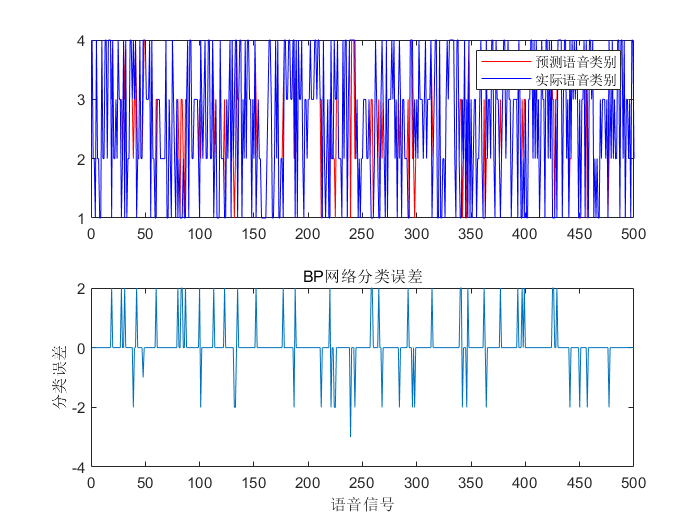

clear; clc;
% 加载四类语音信号
load data1.mat
load data2.mat
load data3.mat
load data4.mat
% 四个特征信号矩阵合成一个矩阵
data(1:500, :) = c1(1:500, :);
data(501:1000, :) = c2(1:500, :);
data(1001:1500, :) = c3(1:500, :);
data(1501:2000, :) = c4(1:500, :);
% 输入输出数据
input = data(:, 2:25);    % 输入信号
output1 = data(:, 1);     % 类型
output = zeros(2000, 4);
for i = 1 : 2000
    switch output1(i)
        case 1
            output(i, :) = [1 0 0 0];
        case 2
            output(i, :) = [0 1 0 0];
        case 3
            output(i, :) = [0 0 1 0];
        case 4
            output(i, :) = [0 0 0 1];
    end
end
% 随机提取1500个样本作为学习样本，剩下500个作为测试样本
n = randperm(2000);
input_train = input(n(1 : 1500), :)';
output_train = output(n(1 : 1500), :)';
input_test = input(n(1501 : 2000), :)';
output_test=output(n(1501 : 2000), :)';
% 输入数据归一化
[inputn, inputps] = mapminmax(input_train);
% 网络结构初始化
innum = 24;      % 输入层
midnum = 20;   % 隐含层
outnum = 4;      % 输出层
%权值初始化
rng('default');   % 结果可重复
w1 = rand(midnum, innum); 
b1= rand(midnum,1);
w2 = rand(midnum, outnum);
b2 = rand(outnum, 1);
w2_1 = w2;
w2_2 = w2;
w1_1 = w1;
w1_2 = w1;
b1_1 = b1;
b1_2 = b1;
b2_1 = b2;
b2_2 = b2;
xite = 0.1;    %学习率
alfa = 0.01;   % 动量学习率
loopNumber = 50;   % 越大越准确
I = zeros(1, midnum);
Iout = zeros(1, midnum);
FI = zeros(1, midnum);
dw1 = zeros(innum, midnum);
db1 = zeros(1, midnum);
% 网络训练
E = zeros(1, loopNumber);
for ii = 1 : loopNumber
     E(ii) = 0;
    for i = 1 : 1500
       % 网络预测输出 
        x = inputn(:, i);
        % 隐含层输出
        for j = 1 : midnum
            I(j) = inputn(:, i)' * w1(j, :)' + b1(j);
            Iout(j) = 1/(1 + exp(-I(j)));
        end
        % 输出层输出
        yn = w2' * Iout' + b2;      
       % 权值阀值修正
        % 计算误差
        e = output_train(:, i) - yn;     
        E(ii) = E(ii) + sum(abs(e));
        % 计算权值变化率
        dw2 = e * Iout;
        db2 = e';
        for j = 1 : midnum
            S = 1/(1 + exp(-I(j)));
            FI(j) = S*(1 - S);
        end      
        for k = 1 : innum
            for j = 1 : midnum
                dw1(k, j) = FI(j) * x(k) * (e(1)*w2(j, 1) + e(2)*w2(j, 2) + e(3)*w2(j, 3) + e(4)*w2(j,4));
                db1(j) = FI(j) * (e(1)*w2(j, 1) + e(2)*w2(j, 2) + e(3)*w2(j, 3) + e(4)*w2(j, 4));
%                 db1(j) = FI(j) * (e' * w2(j, :)');    %  很慢
            end
        end
        w1 = w1_1 + xite*dw1' + alfa*(w1_1 - w1_2);
        b1 = b1_1 + xite*db1' + alfa*(b1_1 - b1_2);
        w2 = w2_1 + xite*dw2' + alfa*(w2_1 - w2_2);
        b2 = b2_1 + xite*db2' + alfa*(b2_1 - b2_2);
        w1_2 = w1_1;
        w1_1 = w1;
        w2_2 = w2_1;
        w2_1 = w2;
        b1_2 = b1_1;
        b1_1 = b1;
        b2_2 = b2_1;
        b2_1 = b2;
    end
end
% 语音特征信号分类
inputn_test = mapminmax('apply', input_test, inputps);
fore = zeros(4, 500);
for i = 1 : 500
    % 隐含层输出
    for j = 1 : midnum
        I(j) = inputn_test(:, i)' * w1(j, :)' + b1(j);
        Iout(j) = 1/(1 + exp(-I(j)));
    end
    fore(:, i) = w2' * Iout' + b2;
end
% 结果分析
% 根据网络输出找出数据属于哪类
output_fore = zeros(1, 500);
for i = 1 : 500
    output_fore(i) = find(fore(:, i) == max(fore(:, i)));
end
% BP网络预测误差
error = output_fore - output1(n(1501 : 2000))';
% 画出预测语音种类和实际语音种类的分类图
subplot(2, 1, 1)
plot(output_fore,'r')
hold on
plot(output1(n(1501 : 2000))', 'b');
hold off
legend('预测语音类别', '实际语音类别')
%画出误差图
subplot(2, 1, 2)
plot(error);
title('BP网络分类误差')
xlabel('语音信号')
ylabel('分类误差')

% 找出判断错误的分类属于哪一类
k = zeros(1, 4);  
for i = 1 : 500
    if error(i) ~= 0
        [~, c] = max(output_test(:, i));
        switch c
            case 1 
                k(1) = k(1) + 1;
            case 2 
                k(2) = k(2) + 1;
            case 3 
                k(3) = k(3) + 1;
            case 4 
                k(4) = k(4) + 1;
        end
    end
end
% 找出每类的个体和
kk = zeros(1, 4);
for i = 1 : 500
    [~, c] = max(output_test(:,i));
    switch c
        case 1
            kk(1) = kk(1) + 1;
        case 2
            kk(2) = kk(2) + 1;
        case 3
            kk(3) = kk(3) + 1;
        case 4
            kk(4) = kk(4) + 1;
    end
end
% 正确率
rightridio = (kk - k) ./ kk;
disp('正确率')

正确率


disp(rightridio);

    0.7054    1.0000    0.9375    0.8936
